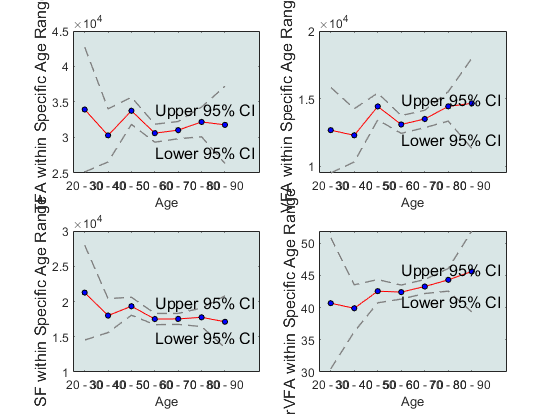

% age and fat, the curve of them

clear
clc

load('BingliFatAnalysis.mat');
FTT = table2array(BingliFatData);
FTT(:,5) = 100*FTT(:,3)./FTT(:,2);
FTT(:,4) = FTT(:,2) - FTT(:,3);

Age = FTT(:,1);
Result = zeros(4, 9);
Upzhixin = zeros(4, 9);
Lowzhixin = zeros(4, 9);
for r=1:4
    Fat_r = FTT(:,1+r);
    for c=1:9
        Age_c = ageindex(c,Age); % 样本容量很小的情况下，如何提升、缩小置信区间呢？在某些假设下，有本质上的好办法吗？
        x = Fat_r(Age_c);  % 可以看出，两端人数较少，比如25对应的才11人。
        alpha = 0.05; % 置信水平为 95%
        [muHat, ~, muCI] = normfit(x, alpha); % 计算均值的置信区间
        if isempty(muCI) 
            muCI = [0,0]';
        end
        if isempty(muHat) 
            muHat = 0;
        end
        Result(r,c) = muHat;
        Lowzhixin(r,c) = muCI(1,1);
        Upzhixin(r,c) = muCI(2,1);
    end
end

% data 是样本数据。
% alpha 是显著性水平，1 - alpha 表示置信水平（例如，alpha = 0.05 对应 95% 置信水平）。
% muCI 是均值的置信区间，返回一个包含上下限的向量。
% normfit 函数会自动根据样本量和 t 分布计算置信区间，非常适合小样本数据的分析

age = [25 35 45 55 65 75 85];

fig4fat = figure;

subplot(2,2,1)
plot(age, Result(1,2:8), 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
hold on
plot(age, Upzhixin(1,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
hold on
plot(age, Lowzhixin(1,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
xlabel('Age')
ylabel('TFA within Specific Age Range','FontSize', 12)
% 自定义横坐标刻度位置和标签
xticks(age); % 设置刻度位置
xticklabels(arrayfun(@(i) sprintf('%.f - %.f', i-5, i+5), age, 'UniformOutput', false)); %%% Help by Zukai
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
       text(55, 34000, 'Upper 95% CI', 'FontSize', 12);
       text(55, 28000, 'Lower 95% CI', 'FontSize', 12);

subplot(2,2,2)
plot(age, Result(2,2:8), 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
hold on
plot(age, Upzhixin(2,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
hold on
plot(age, Lowzhixin(2,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
xlabel('Age')
ylabel('VFA within Specific Age Range','FontSize', 12)
% 自定义横坐标刻度位置和标签
xticks(age); % 设置刻度位置
xticklabels(arrayfun(@(i) sprintf('%.f - %.f', i-5, i+5), age, 'UniformOutput', false)); %%% Help by Zukai
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
       text(55, 15000, 'Upper 95% CI', 'FontSize', 12);
       text(55, 12000, 'Lower 95% CI', 'FontSize', 12);


subplot(2,2,3)
plot(age, Result(3,2:8), 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
hold on
plot(age, Upzhixin(3,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
hold on
plot(age, Lowzhixin(3,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
xlabel('Age')
ylabel('SF within Specific Age Range','FontSize', 12)
% 自定义横坐标刻度位置和标签
xticks(age); % 设置刻度位置
xticklabels(arrayfun(@(i) sprintf('%.f - %.f', i-5, i+5), age, 'UniformOutput', false)); %%% Help by Zukai
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
       text(55, 20000, 'Upper 95% CI', 'FontSize', 12);
       text(55, 15000, 'Lower 95% CI', 'FontSize', 12);

subplot(2,2,4)
plot(age, Result(4,2:8), 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
hold on
plot(age, Upzhixin(4,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
hold on
plot(age, Lowzhixin(4,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1);
xlabel('Age')
ylabel('rVFA within Specific Age Range','FontSize', 12)
% 自定义横坐标刻度位置和标签
xticks(age); % 设置刻度位置
xticklabels(arrayfun(@(i) sprintf('%.f - %.f', i-5, i+5), age, 'UniformOutput', false)); %%% Help by Zukai
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
       text(55, 46, 'Upper 95% CI', 'FontSize', 12);
       text(55, 41, 'Lower 95% CI', 'FontSize', 12);
       
exportgraphics(fig4fat, 'Figure22Age4Fat.tif','resolution',300);

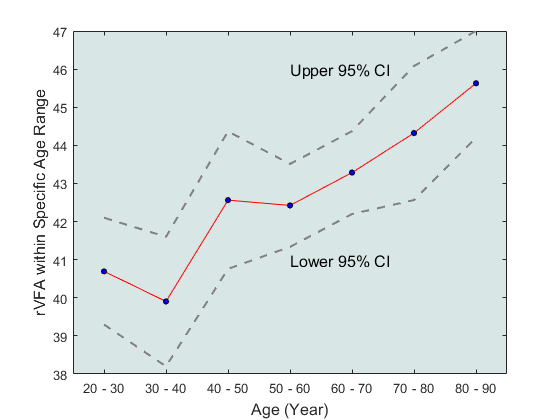




fig = figure;
% 这里改一下第一个置信区间和最后一个置信区间的值：我们相信这里是数据量太少的原因！ 可以吗？
Upzhixin(4,2) = 42.1; Upzhixin(4,3) = 41.6;Upzhixin(4,8) = 47;
Lowzhixin(4,2) = 39.3; Lowzhixin(4,3) = 38.2;Lowzhixin(4,8) = 44.2; % 置信区间一定是对称的！
plot(age, Result(4,2:8), 'r-o', 'MarkerSize', 4, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k');
hold on
plot(age, Upzhixin(4,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1.5);
hold on
plot(age, Lowzhixin(4,2:8), '--', 'Color',[0.5,0.5,0.5],'LineWidth',1.5);
xlabel('Age (Year)','FontSize', 12)
ylabel('rVFA within Specific Age Range','FontSize', 12)
% 自定义横坐标刻度位置和标签
xticks(age); % 设置刻度位置
xticklabels(arrayfun(@(i) sprintf('%.f - %.f', i-5, i+5), age, 'UniformOutput', false)); %%% Help by Zukai
       set(gcf, 'Color', [1 1 1]); % 设置图形窗口背景为bai色
       set(gca, 'Color', [0.85, 0.9, 0.9]); % 设置坐标轴背景为qianhuilan色
       text(55, 46, 'Upper 95% CI', 'FontSize', 12);
       text(55, 41, 'Lower 95% CI', 'FontSize', 12);
       
exportgraphics(fig, 'Figure2AgeFat.tif','resolution',300);